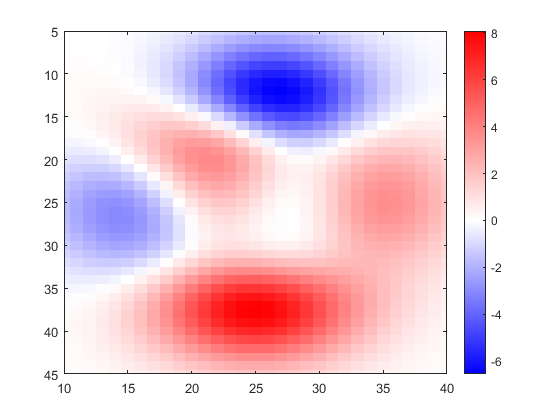

clear all;

data = peaks;

MidValue = 0;   %value to set white to

MaxColor = [1 0 0]; %sets maximum color to red
MinColor = [0 0 1]; %sets minimum color to blue
MidColor = [1 1 1]; %sets midpoint to white

mindata = min(min(data));
maxdata = max(max(data));
index = numel(data)*abs(MidValue-mindata)./(maxdata-mindata);

CustomMapTop = [linspace(MinColor(1),MidColor(1),index)',linspace(MinColor(2),MidColor(2),index)',linspace(MinColor(3),MidColor(3),index)'];
CustomMapBot = [linspace(MidColor(1),MaxColor(1),(numel(data)-index))',linspace(MidColor(2),MaxColor(2),(numel(data)-index))',linspace(MidColor(3),MaxColor(2),(numel(data)-index))'];

CustM = [CustomMapTop;CustomMapBot];

colormap(figure(1),CustM);
colormap(figure(2),parula)

figure(1);
imagesc(data)
xlim([10,40]);
ylim([5,45]);
colorbar;

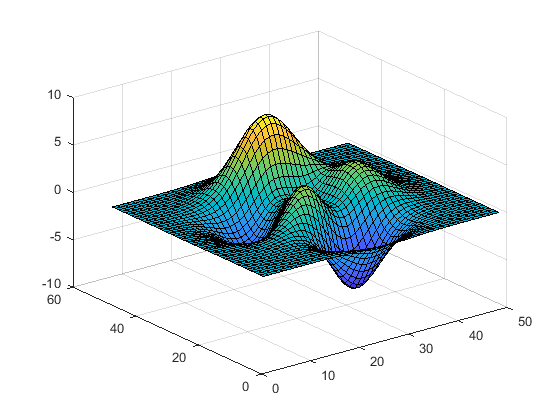


figure(2);
surf(peaks);